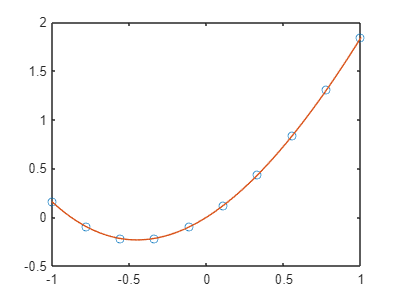

% Creare un'interpolazione polinomiale di una funzione
% non lineare utilizzando il metodo dei minimi quadrati

clear all;

% Definizione della funzione e dei punti di interpolazione
x = linspace(-1, 1, 10);
y = sin(x) + x.^(2);

% Utilizzo il metodo dei minimi quadrati per calcolare i
% coefficenti del polinomio interpolante
n = 5;
coeff = polyfit(x, y, n+1);

% Utilizzo i nuovi coefficienti per generare la 
% la funzione interpolante
x1 = linspace(-1, 1, 1000);
y1 = polyval(coeff, x1);

% Plot dei risultati
plot(x, y, 'o');
hold on;
plot(x1, y1, '-');